# Extrapolation ordre 0

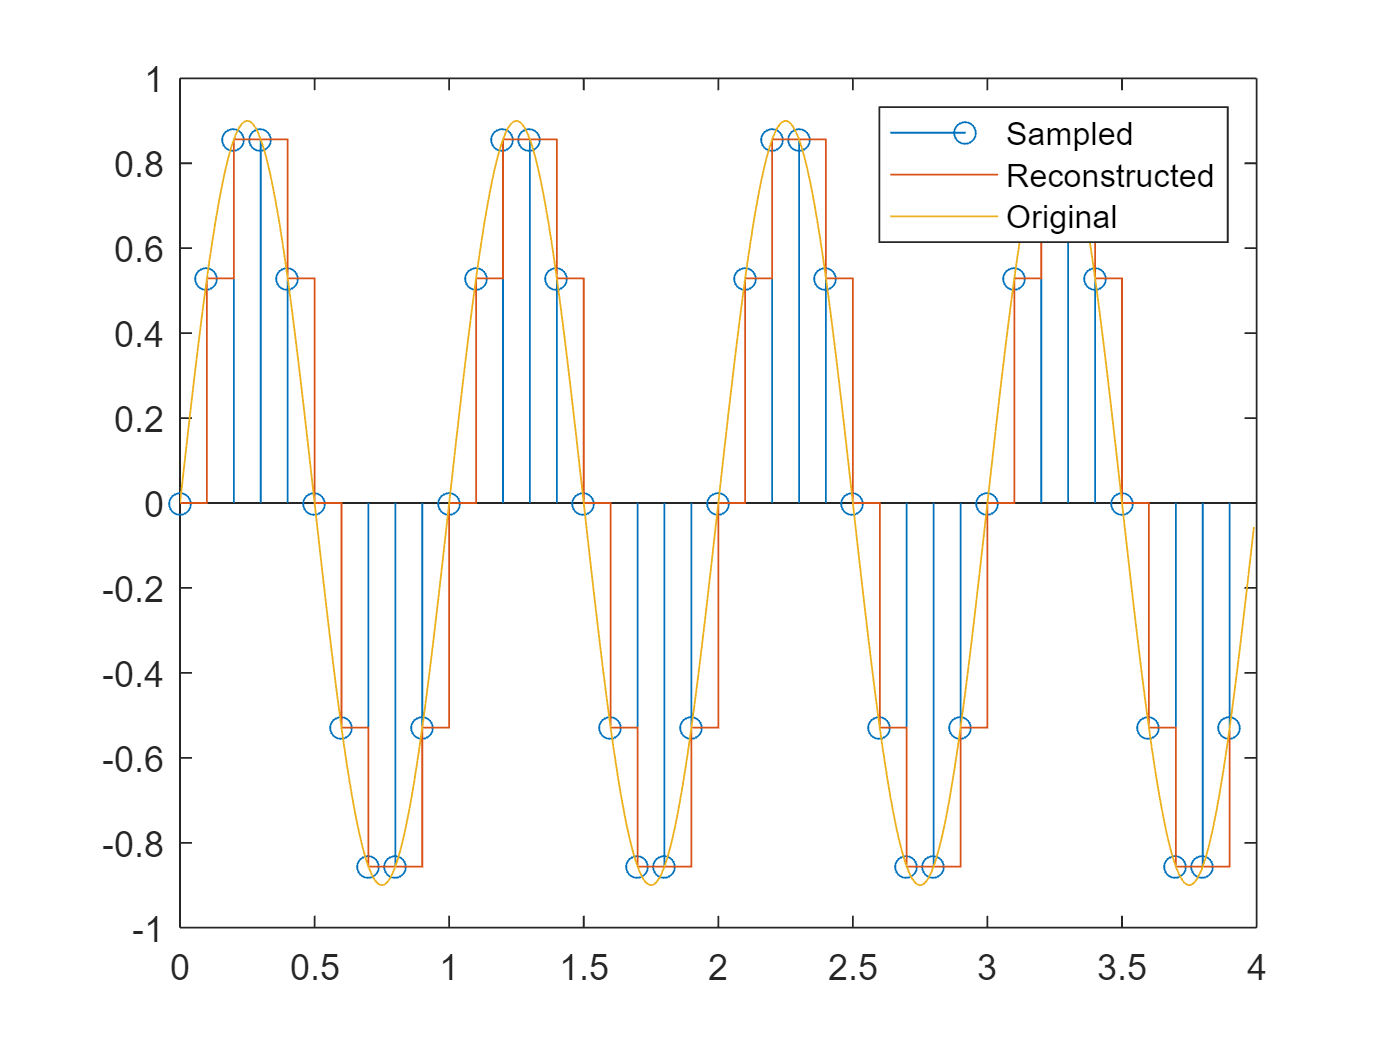

fs = 10;
ups = 10;
t = 0:1/fs:4-1/fs;
fs1=fs*ups;
t1= 0:1/fs1:4-1/fs1;
x = .9*sin(2*pi*t);
s = .9*sin(2*pi*t1);
stem(t,x)
hold on
stairs(t,x)
plot(t1,s)
legend(["Sampled","Reconstructed","Original"])
hold off

### **Reconstruction**


fu = fs*ups;
tu = 0:1/fu:4-1/fu;
y = upsample(x,ups);
h = ones(ups,1);
figure
z = filter(h,1,y);

% stem(tu,z)
% hold on
% stairs(t,x)
% hold off

## Fourier

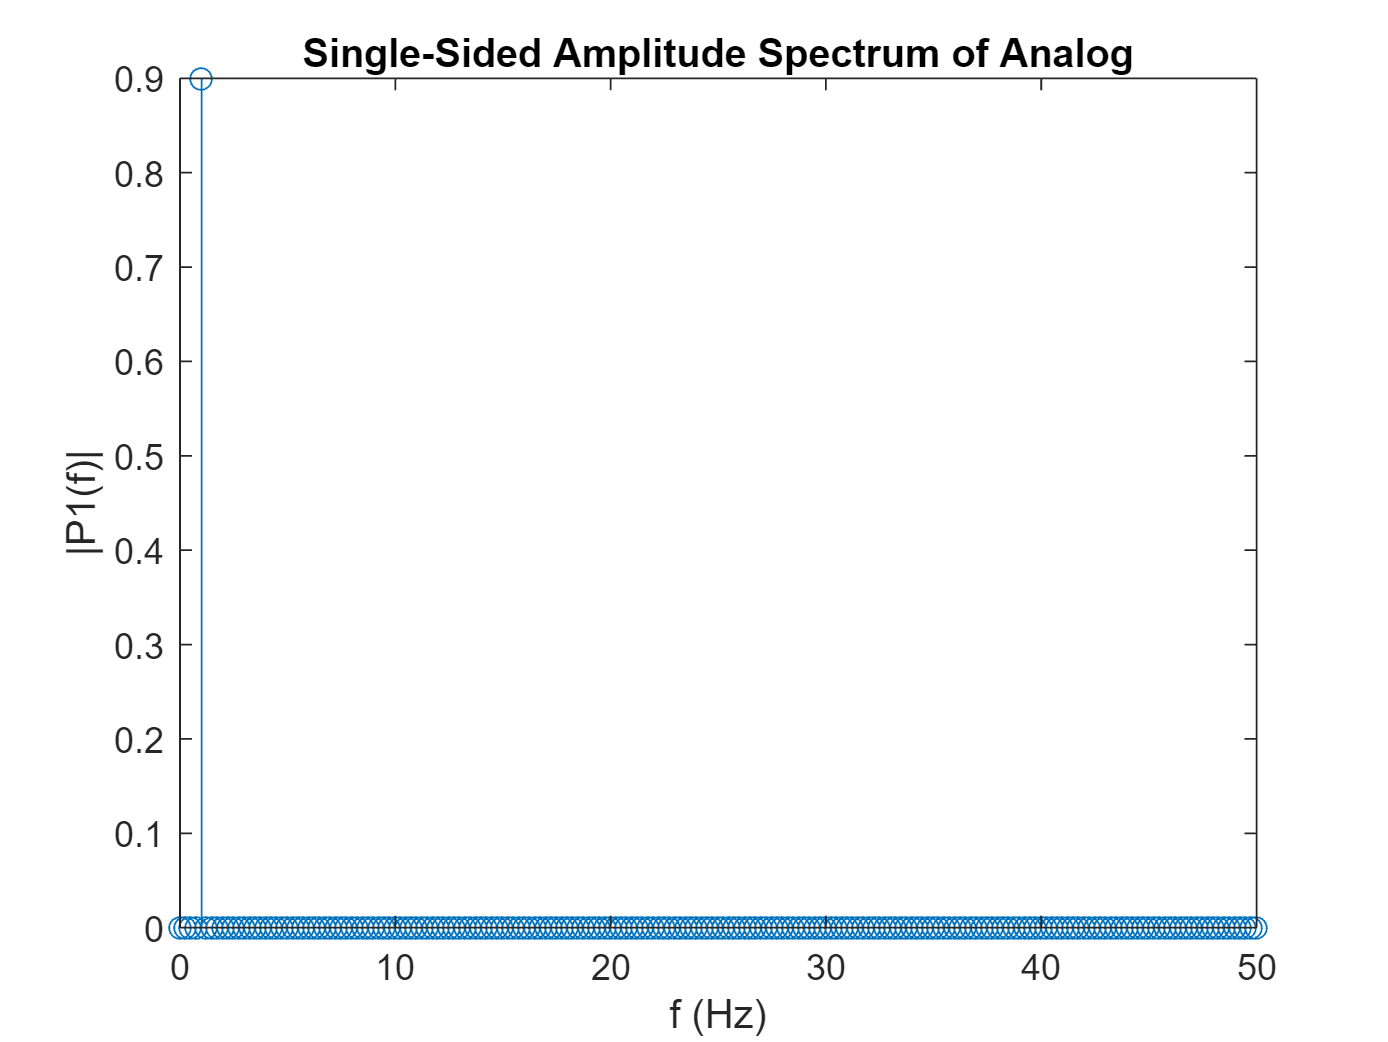

L =length(tu);
Y = fft(s);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
%Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

f = fu*(0:(L/2))/L;
stem(f,P1) 
title("Single-Sided Amplitude Spectrum of Analog")
xlabel("f (Hz)")
ylabel("|P1(f)|")

L =1000

L = 1000

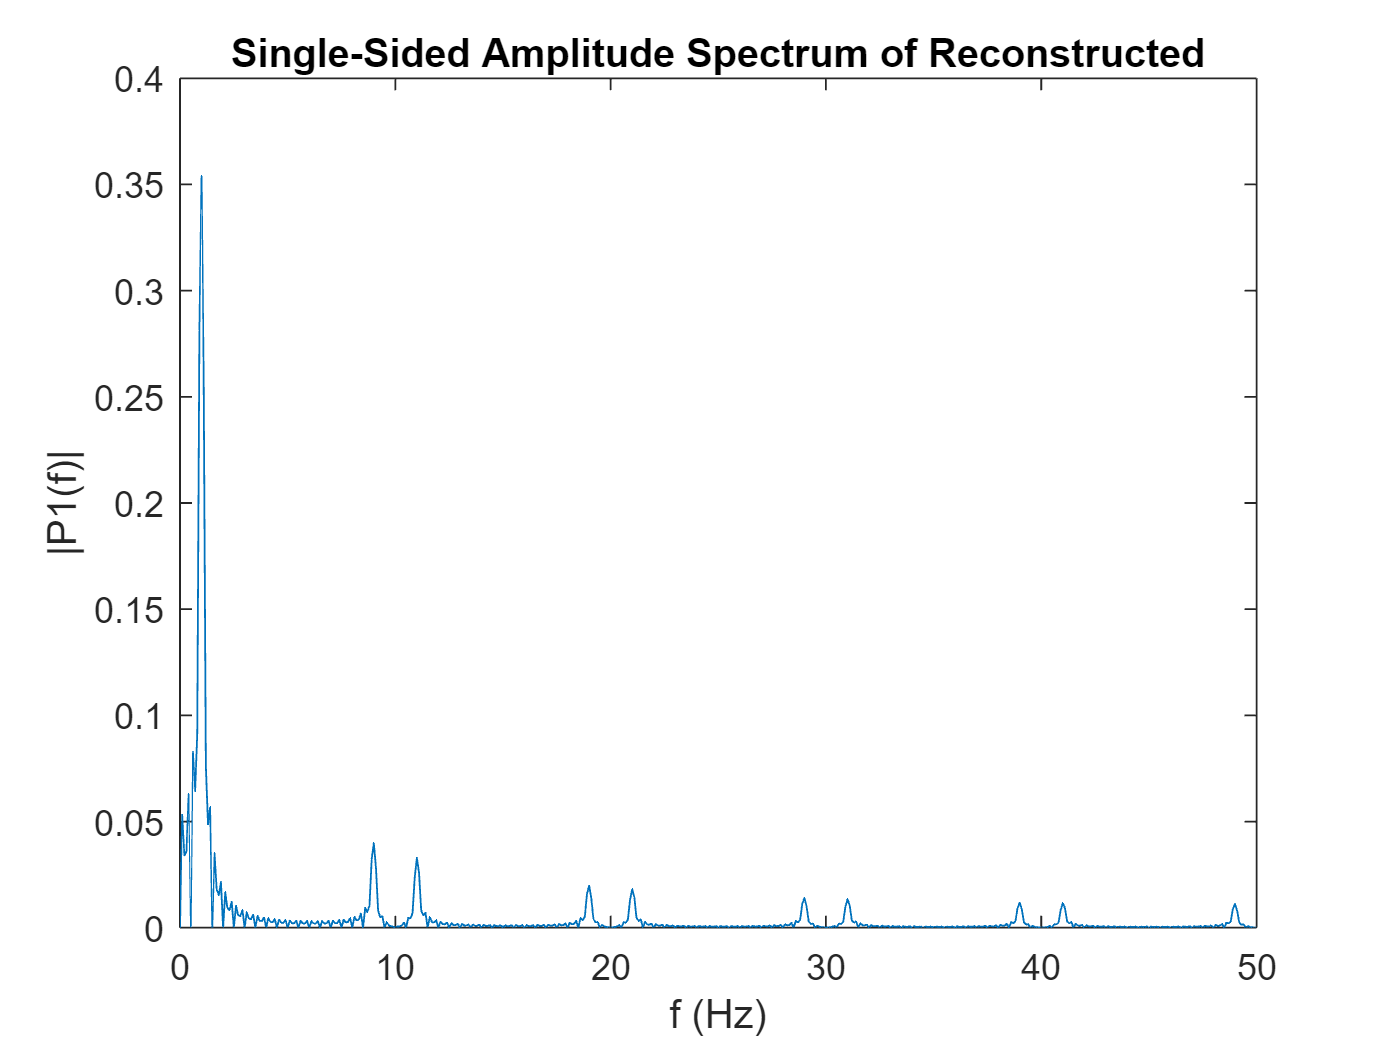

Y = fft(z,L);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
%Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

f = fu*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of Reconstructed")
xlabel("f (Hz)")
ylabel("|P1(f)|")